part1=data_sEMG(1:32,:);
part2=data_sEMG(33:64,:);
part3=data_sEMG(65:96,:);
part4=data_sEMG(97:128,:);

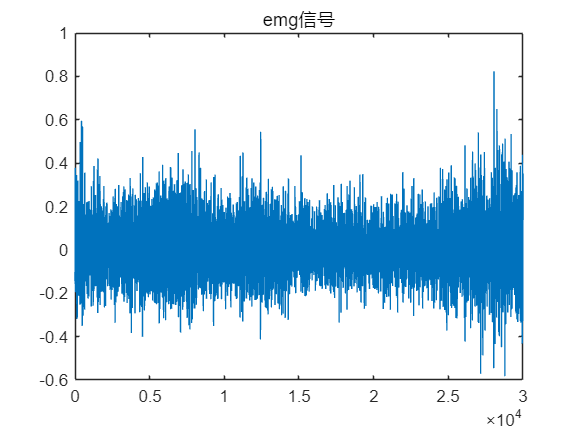

 % signal=part1(17,:);

% signal=twitchCurves{1}{2};
 % signal=decompData{1}(17,:);
% signal=double(datafilt(2,:));
% signal=CKCdecomp{2,3}.datafilt(1,:);%CKC解码

signal=Data{1}(:,2);
% signal=data_sEMG(2,:)';
% signal=datafilt(2,:)';

% signal=iEMG;

Fs=2000;
clf;a=plot(signal); title('emg信号')

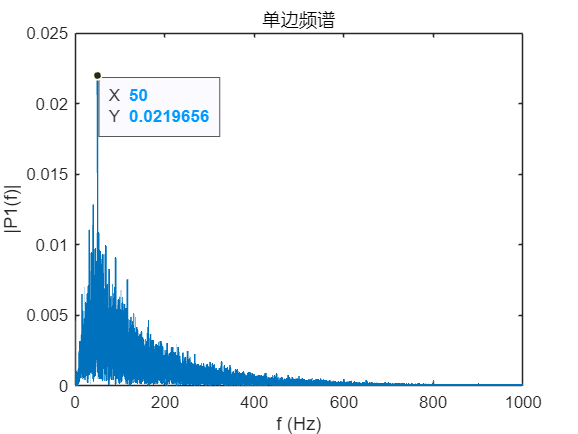

Y=fft(signal);


L=length(signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);f = Fs/L*(0:(L/2));
plot(f,P1,"LineWidth",1) 
title("单边频谱")
xlabel("f (Hz)")
ylabel("|P1(f)|")

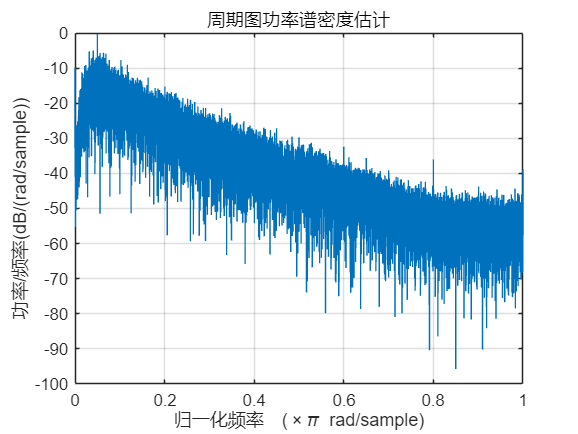

periodogram(signal)  

% sig_filt=filter(Num,Den,signal);
% plot(sig_filt);
fsamp=10240

fsamp = 10240

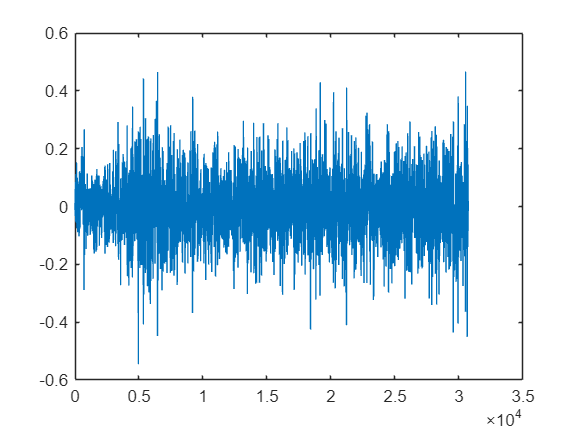

LowFreq = 100;   % low frequency of passband
    HighFreq = 1000; % high frequency of passband
    % signalQuality = 5;  % frequency criterion

    % Bandpass filter the vector array Y, pass band LowFreq-HighFreq 
[Be,Ae] = butter(4,[LowFreq/fsamp*2 HighFreq/fsamp*2]); % EMG band pass filter
sig=filtfilt(Be,Ae,signal);
fo = 50; % power frequency
q = 5;
bw = (fo/(fsamp/2))/q;
[Be,Ae] = iircomb(round(fsamp/fo),bw,'notch');%%%梳状滤波
sig=filtfilt(Be,Ae,sig);
plot(sig);

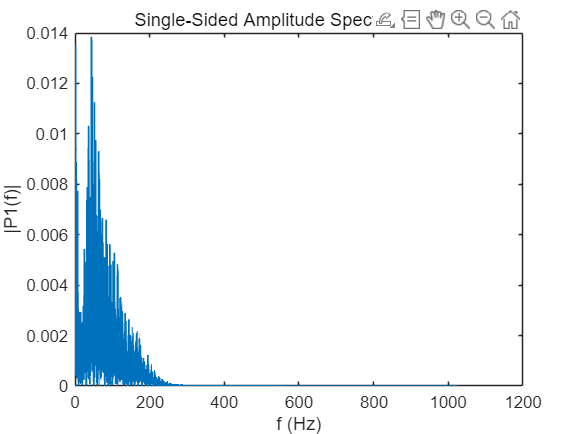

Y=fft(sig);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);f = Fs/L*(0:(L/2));
plot(f,P1,"LineWidth",1)
title("Single-Sided Amplitude Spectrum of X(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

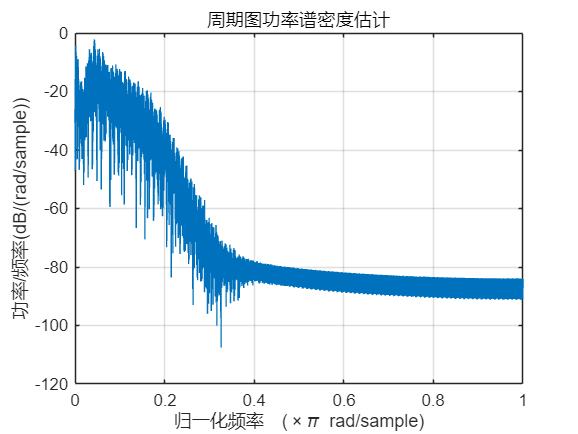

periodogram(sig)  

sig=filter(Hd,sig);
Y=fft(sig);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);f = Fs/L*(0:(L/2));
plot(f,P1,"LineWidth",1) 
title("Single-Sided Amplitude Spectrum of X(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")
